# Curve Fitting

*Bart Krekelberg - Last Update Jan 2023.*

Fitting procedures answer the question: "Does this look like that?" This is a frequent question in data analysis: does this set of measurments look similar to the other set of measurements? Does this set of measurements look like the predictions of this model? Which of these models do the measurements look like most? In this module we'll look at a few techniques to answer these questions quantitatively.

## Correlation

You perform an experiment in which the pitch of an auditory signal is varied, and the firing rate of a neuron in A1 recorded:

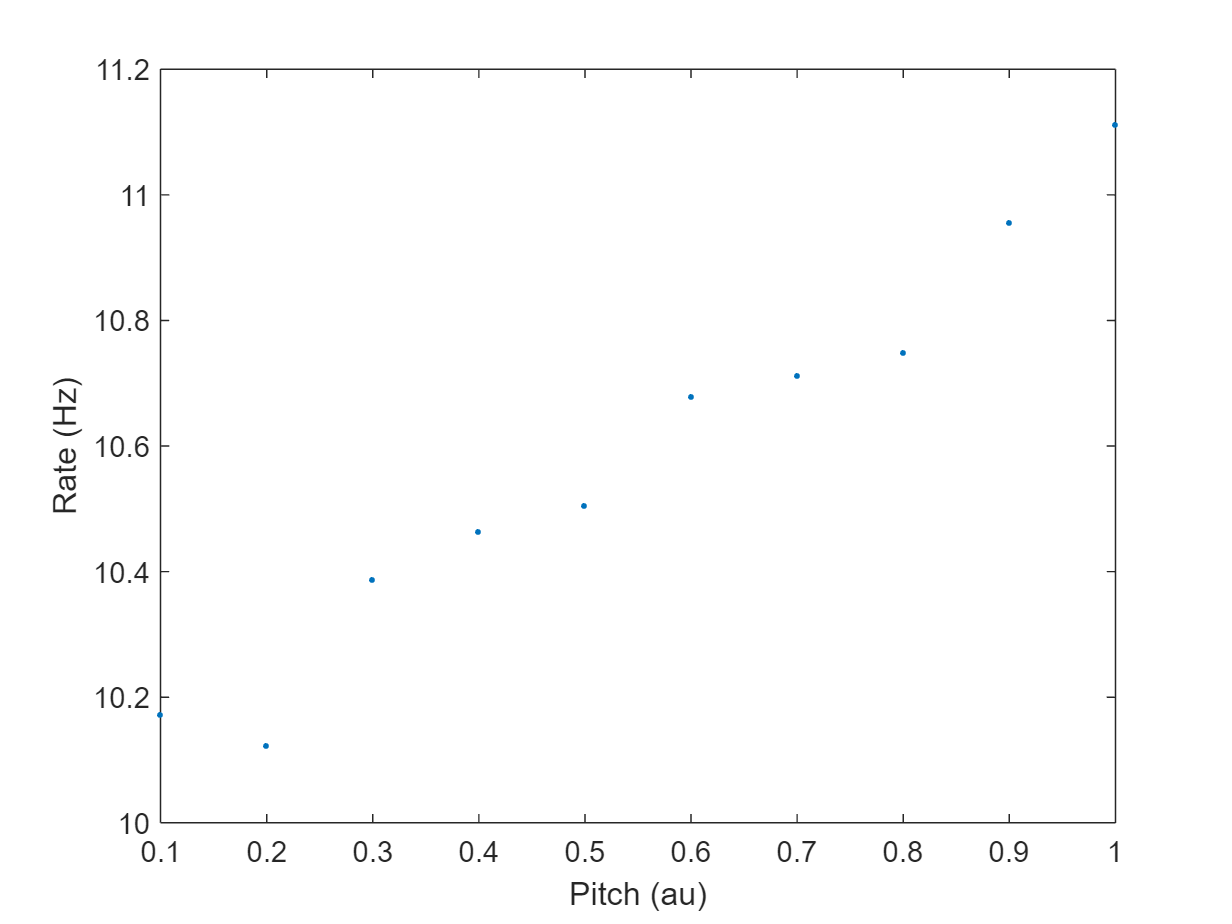

addpath('../code'); % Put the neuralResponse function on Matlab's search path
nrStimuli = 10;
maxPitch  = 1;
minPitch = 0.1;
pitch = linspace(minPitch,maxPitch,nrStimuli)'; % Pitch of the input signal
spontaneousRate = 10;
noiseLevel = 0.05;
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel);

figure;
plot(pitch,meanFiringRate,'.');
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

Based on this exploratory plot you hypothesize that the picth of the tone determines the firing rate of the neuron. 

### Linear Relationships (Pearson)

To quantify this, you can use a measure of correlation. The simplest measure is the Pearson Correlation Coefficient. 

pearson  =corr(pitch,meanFiringRate,'type','pearson') %#ok<*NASGU> 

pearson = 0.9813

The Pearson correlation is a number that is always between -1 and 1. Its value says something about how well you can predict the one measure (`firingRate` in this case) from the other (`pitch`). To develop an intuition for this, we calculate the Pearson correlation for a range of noise levels:

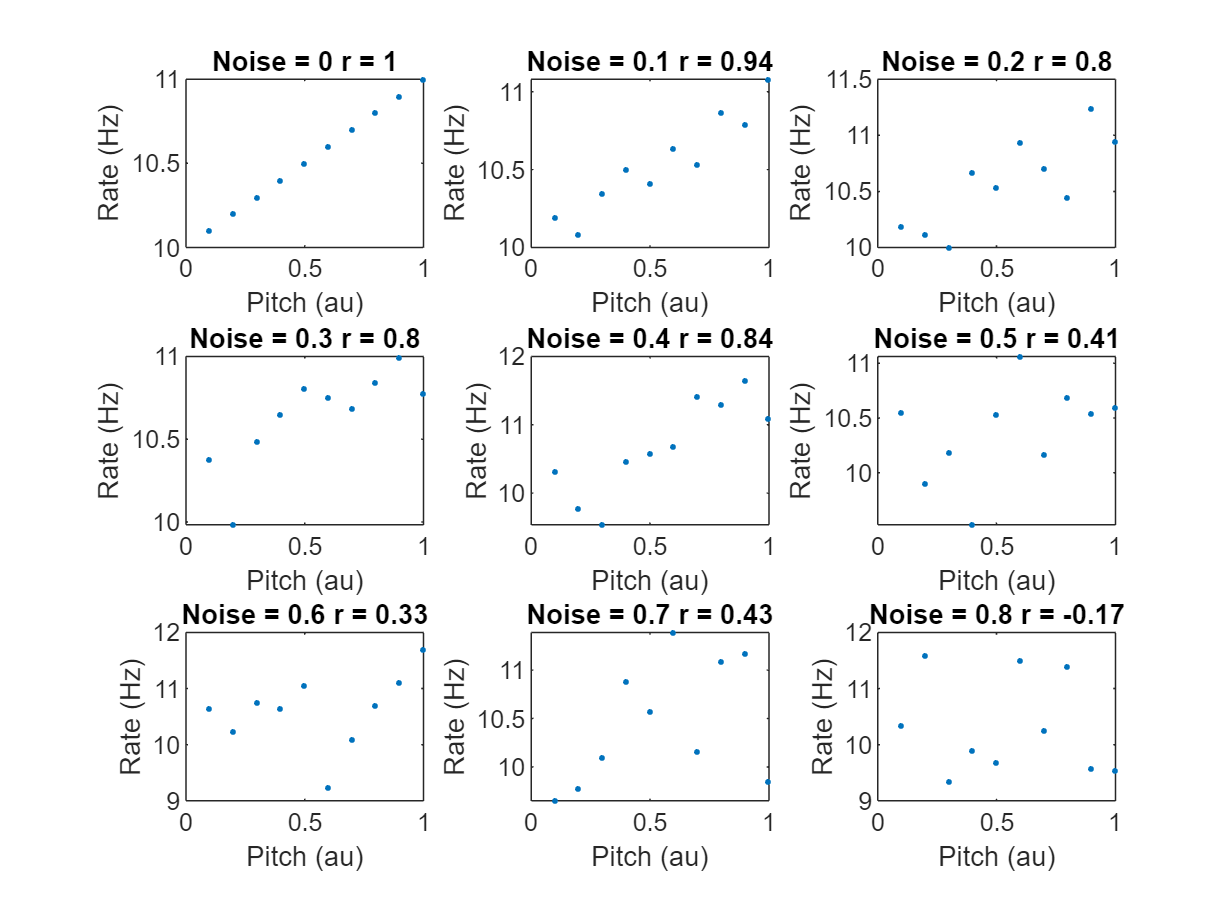

noiseLevel = 0:0.1:0.8;
nrNoiseLevels = numel(noiseLevel);
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel);
clf;
R = floor(sqrt(nrNoiseLevels));
C = ceil(nrNoiseLevels/R);
pearson = nan(nrNoiseLevels,1);
for i=1:nrNoiseLevels
    subplot(R,C,i);
    plot(pitch,meanFiringRate(:,i),'.');
    pearson(i) = corr(pitch,meanFiringRate(:,i),'type','pearson');
    title(['Noise = ' num2str(noiseLevel(i)) ' r = ' num2str(pearson(i),2)]);
    xlabel 'Pitch (au)'
    ylabel 'Rate (Hz)'
end

When there is no noise (`noiseLevel=0`) the `pitch` perfectly predicts the firing rate and this relationship is (by construction in the `neuralResponse` function) linear (`y=a*x+b`). That is what results in a Pearson correlation of exactly 1. You can see that with increase amounts of noise, the relationship becomes fuzzier, and the magnitude of the Pearson correlation reflects this. By eye, I start to loose faith in the relationship somewhere in the second row. (I.e. at that point it would be hard to argue that there is a reliable link between pitch and meanFiringRate.) The `corr` function has a built in statistical significance test to buttress this statement. The function returns the p-value for the null hypothesis that the correlation is zero. 

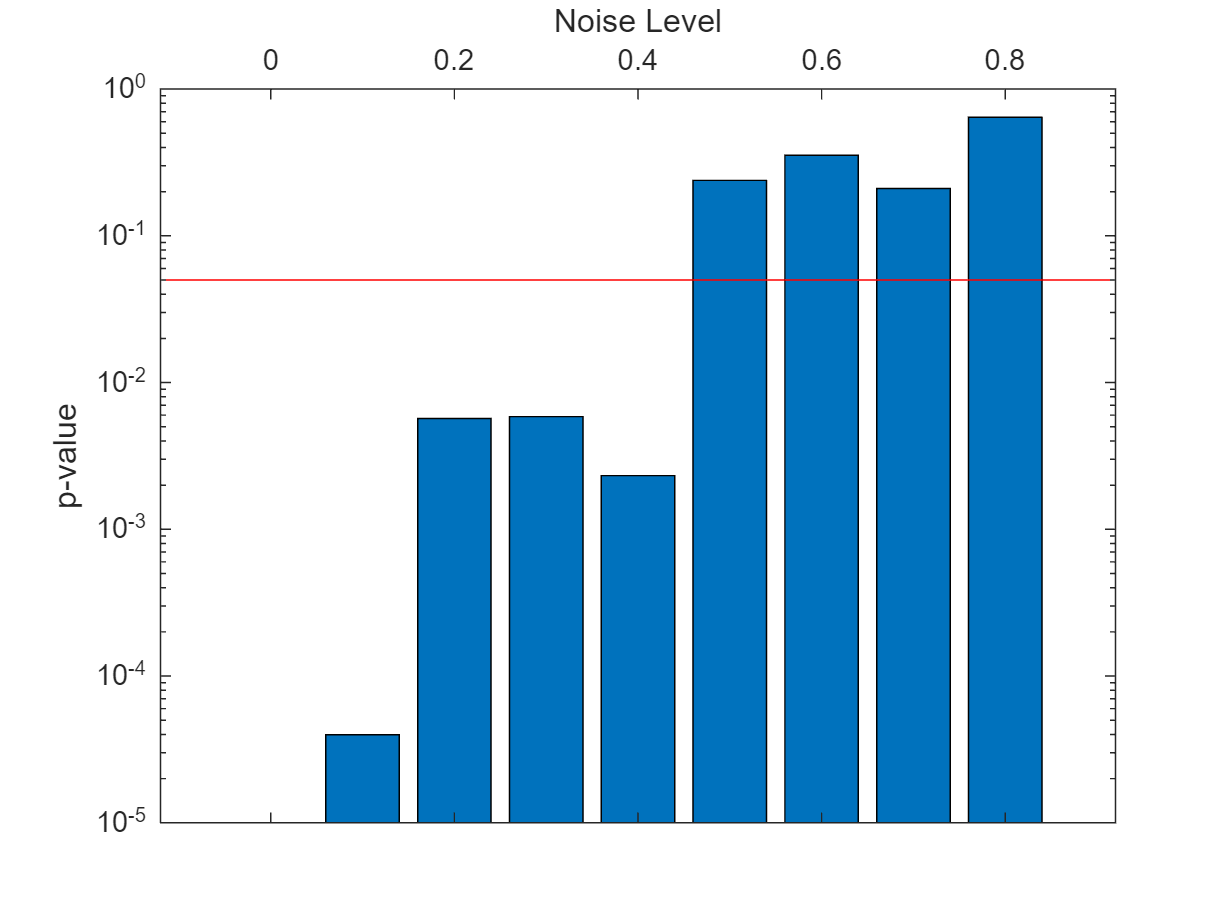

pearson = nan(nrNoiseLevels,1);
p = nan(nrNoiseLevels,1);
for i=1:numel(noiseLevel)
    [pearson(i),p(i)] = corr(pitch,meanFiringRate(:,i),'type','pearson');
end
clf;
bar(noiseLevel,p);
hold on
plot(xlim,0.05*ones(1,2),'r'); % Show a significance level of 0.05
set(gca,'YScale','log','XAxisLocation','top')
ylabel 'p-value'
xlabel 'Noise Level'

As you can see, the first few data sets (at low noise levels) resulted in a significant Pearson correlation, but for higher noise levels the correlation became non-significant, in agreement with the visual impression generated by the scatter plots. 

Please note that the significance of a correlation value depends strongly on the number of data points. For instance a correlation of 0.5 with 10 data points is not very meaningful, but that same correlation value obtained with 100 data points would be highly significant.

Our simulated neuron generated higher firing rates for higher pitch (i.e. it preferred high-pitch sounds). But Pearson correlation works just the same way for a neuron that prefers low pitch:

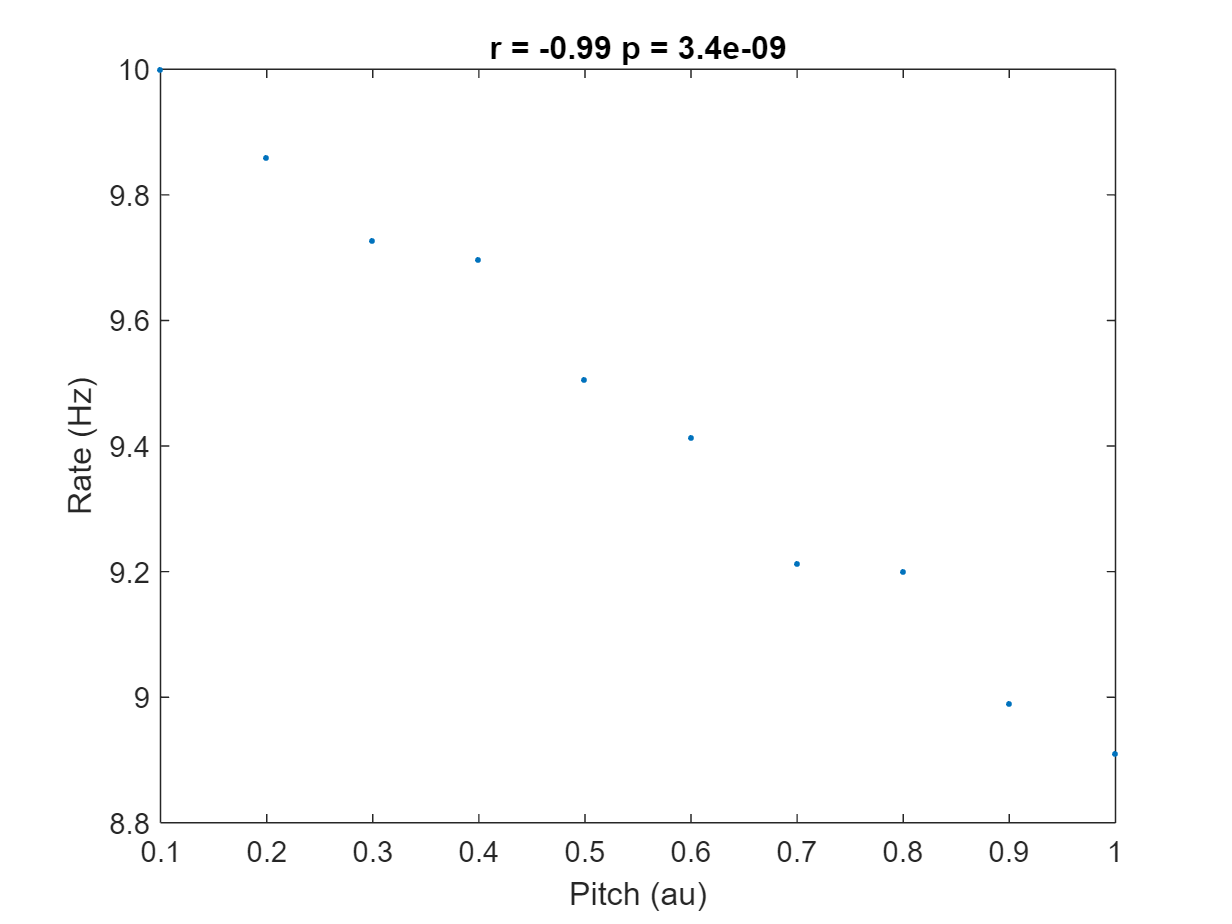

noiseLevel = 0.1;
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel,'model','decrease');
[pearson,p]  =corr(pitch,meanFiringRate,'type','pearson');

clf;
plot(pitch,meanFiringRate,'.');
title(['r = ' num2str(pearson,2) , ' p = ' num2str(p,2)]);
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

As you can see the correlation is strong, but negative. This reflects the fact that in this neuron an increase in pitch results in decrease in firing rate. Siginficance testing is done just the same as for a positive correlation, and by default tests the null hypotehsis that the correlation is zero. If your alternative hypotehsis is more specific (e.g. you had the prior knowledge that firing rate *decreases* with pitch ) then you can use a one-tailed test to specifically test for a negative correlation (See `help corr`). 

*To summarize: the Pearson correlation answers the question: "how much does my data look like the* ***linear**** function: y=ax+b.* 

### Nonlinear relationships (Spearman)

So what happens if your data is not well described by such a linear relationship?

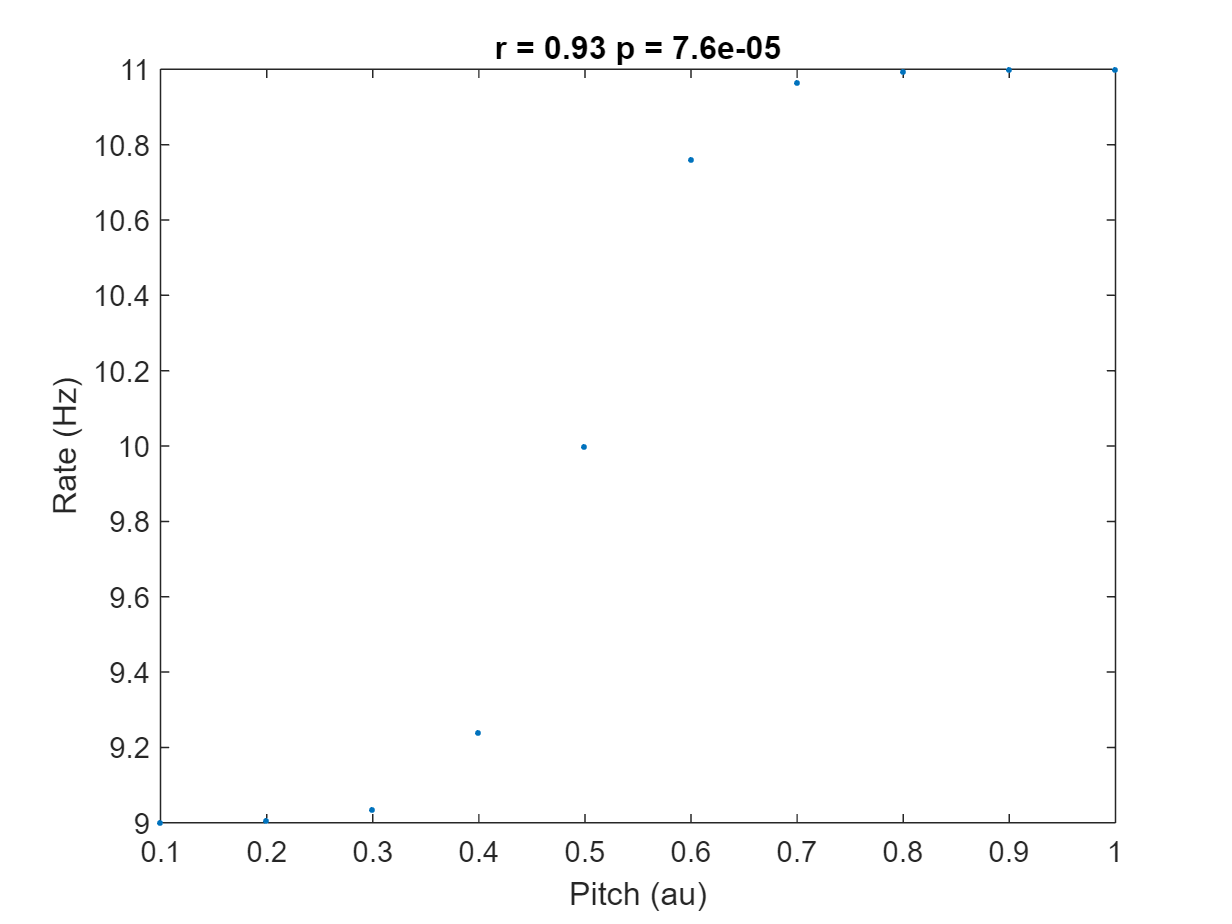

noiseLevel =0;
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel,'model','sigmoid');
[pearson,p]  =corr(pitch,meanFiringRate,'type','pearson');

clf;
plot(pitch,meanFiringRate,'.');
title(['r = ' num2str(pearson,2) , ' p = ' num2str(p,2)]);
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

The noise level is zero, which means that the `pitch` prefectly predicts the firng rate. Nevertheless, the Pearson correlation is not 1. In this case, the conclusion about a significant relationship is still supported by the data (i.e. p<0.05). However, the fact that `r <1` even though there is no noise shows that we are missing something. That something is the *linear* relationship: this neuron's mean firing rate is lawfully, but *not linearly* related to pitch and that is why the Pearson correlation is not the best measure of correlation. Note that it is not wrong to use Pearson correlation but it is just likely that, with noisy data, you'll miss detecting some reliable relationships that are not linear. 

A simple way to look at more general relationships is to use the Spearman correlation. This measure of correlation is based on the *ranks* of the data, and as a consequence the shape of the relationship does not matter. The Spearman correlation is 1 for any monotonically increasing relationship (and -1 for any monotonically decreasing relationship). The `corr` function can calculate the Spearman correlation and its statistical significance:

[spearman,p]  =corr(pitch,meanFiringRate,'type','spearman') %#ok<ASGLU> 

spearman = 1

p = 0

*The Spearman correlation answers the question: "how much does my data look like* ***any arbitrary monotonic function****?"*

Spearman correlation is a non-parameteric measure of correlation. This means that it does not assume that the underlying relationship has a linear shape, nor does it assume anything about the noise on your measurements. 

This is different for the Pearson correlation, which assumes a linear shape and to determine the significance it assumes that the measurement noise is normal. These assumptions give the Pearson correlation a little more power (i.e. if there is a linear relationship and normal noise, then the Pearson correlation will detect it more frequently than the Spearman correlation). The decision whether you need this extra power (at the cost of missing nonlinear relationships) is something that has to be made on a case by case basis (often after doing exploratory data analysis to get an idea of the general shape of the relationships).

## Curve Fitting

Pearson works to discover linear relationships, Spearman discovers monotonic relationships, but what about non-monotonic relationships? This is the domain of curve fitting. Here we ask the general question:"Do these data look like this function?" Matlab has several functions for curve fitting, we'll look at lsqcurvefit here first.

noiseLevel = 0.0;
rng default; 
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel,'model','tuned');
[pearson,pPearson]  =corr(pitch,meanFiringRate,'type','pearson');
[spearman,pSpearman]  =corr(pitch,meanFiringRate,'type','spearman')

spearman = -0.2761

pSpearman = 0.4400

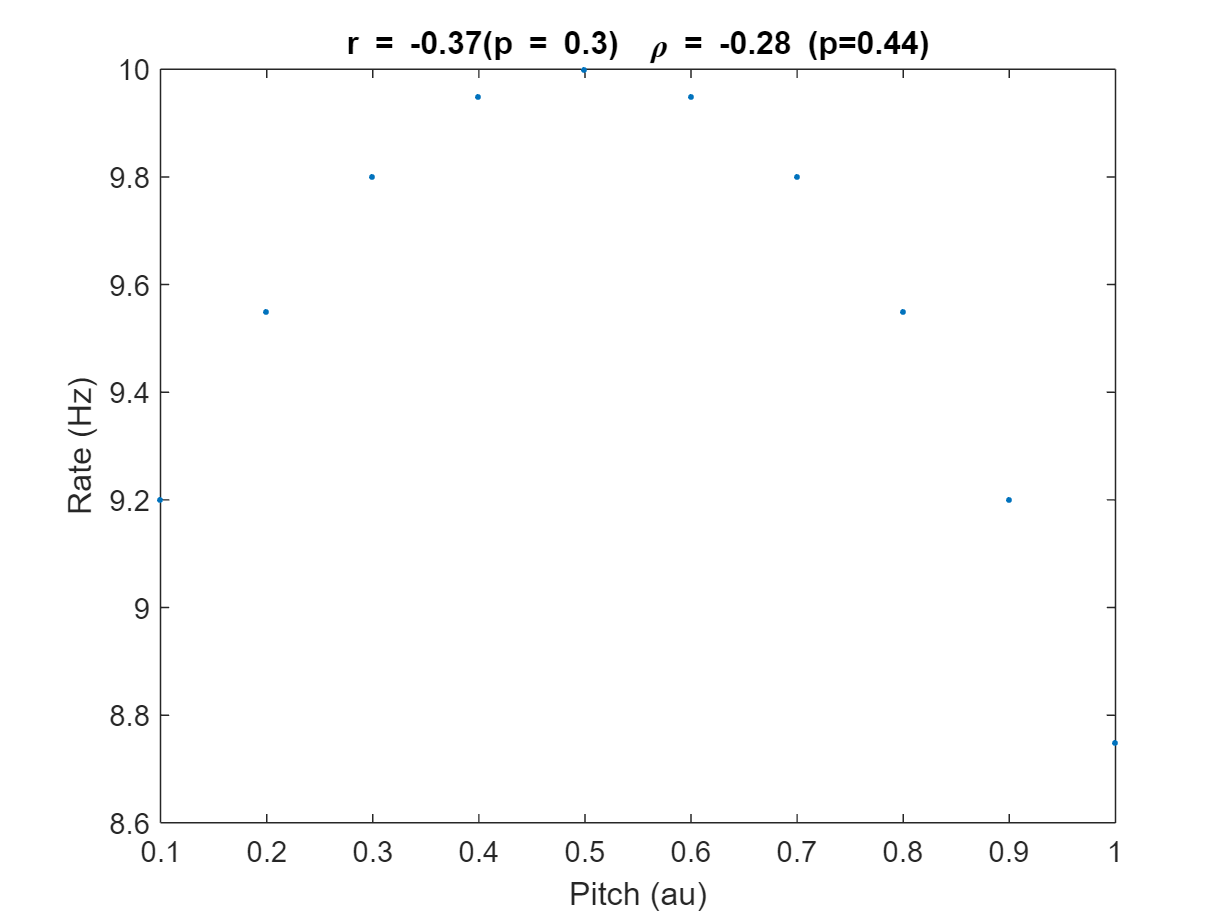


clf;
plot(pitch,meanFiringRate,'.');
title(['r = ' num2str(pearson,2) , '(p = ' num2str(pPearson,2) , ')  \rho = ' num2str(spearman,2) ' (p=' num2str(pSpearman,2) ')']);
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

Not surprisingly, neither the Pearson nor the Spearman correlation are significant. Of course that is because the relationship between pitch and rate is neither linear nor monotonic.

But based on our exploratory data analysis (i.e. looking at the raw data) we hypothesize that the could be a quadratic relationship betwen pitch and rate. First let's define an anonymous function to describe this relationship in abstract terms (You could define this in a separate m-file just as a regular function, but for curve fitting it is often convenient to define anonymous functions inline).

quadratic = @(parms,x) (parms(1).*x.^2 +parms(2).*x +parms(3));

This may look a little scary but it is equivalent to an m-file that looks like this:

We can use the `quadratic` function handle just like any funciton:

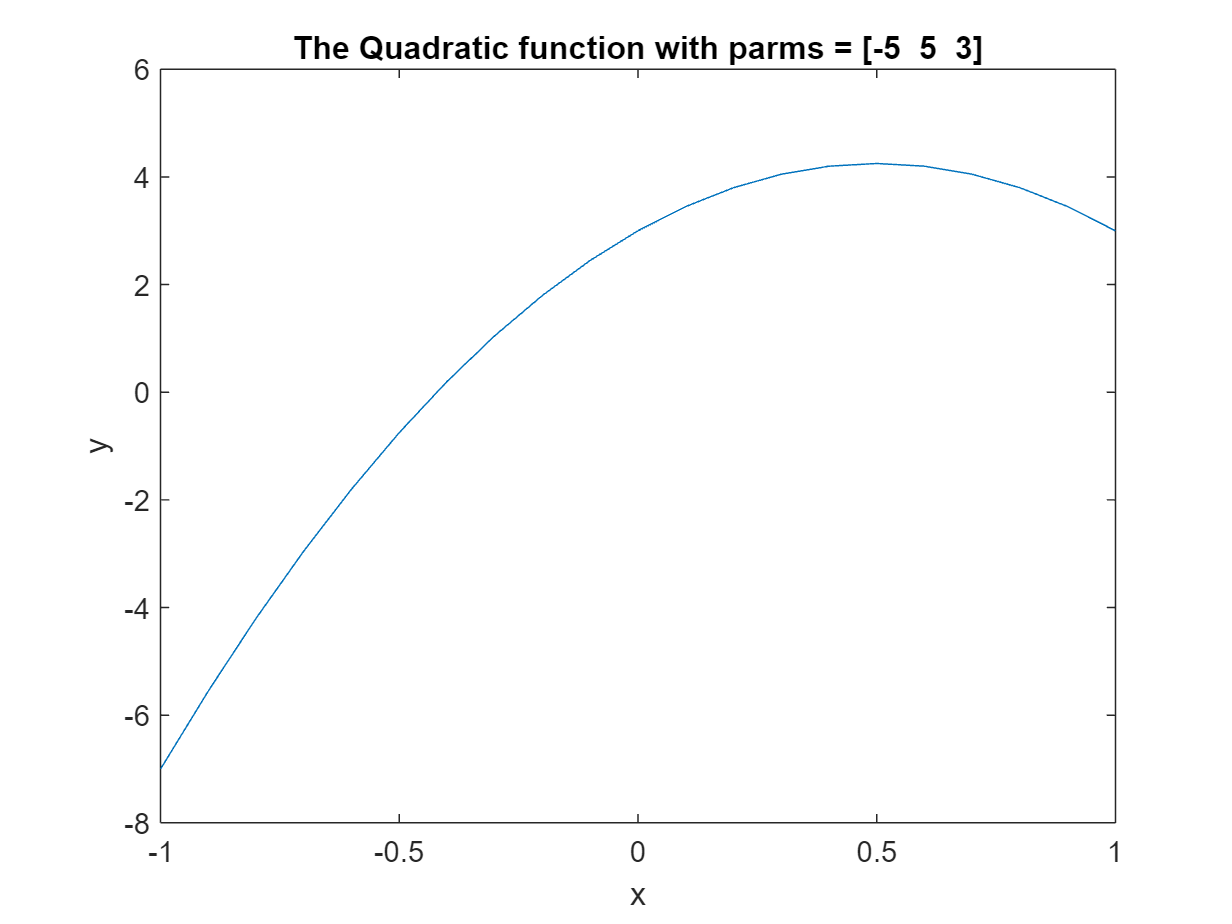

clf;
x = -1:0.1:1;
parms = [-5,5,3];
plot(x,quadratic(parms,x))
xlabel 'x'
ylabel 'y'
title (['The Quadratic function with parms = [' num2str(parms) ']']);

Now we can ask the question: "does the relationship between `pitch` and `meanFiringRate` look like the `quadratic` function? The `lsqurvefit` function is most suitable for this:

guess = [1 1 1];
bestParms = lsqcurvefit(quadratic,guess,pitch,meanFiringRate);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


The `lsqcurvefit` function (least squares curve fit) will search for the `parms` that best reproduce the relationship between `pitch` and `meanFiringRate`. % This search starts at the initial `guess`. Note that there are a number of options to the `lsqcurvefit` function and that the function writes out various comments to the command line that should help to interpret the outcome of the search for the best fit. Let's see how well the search worked. 

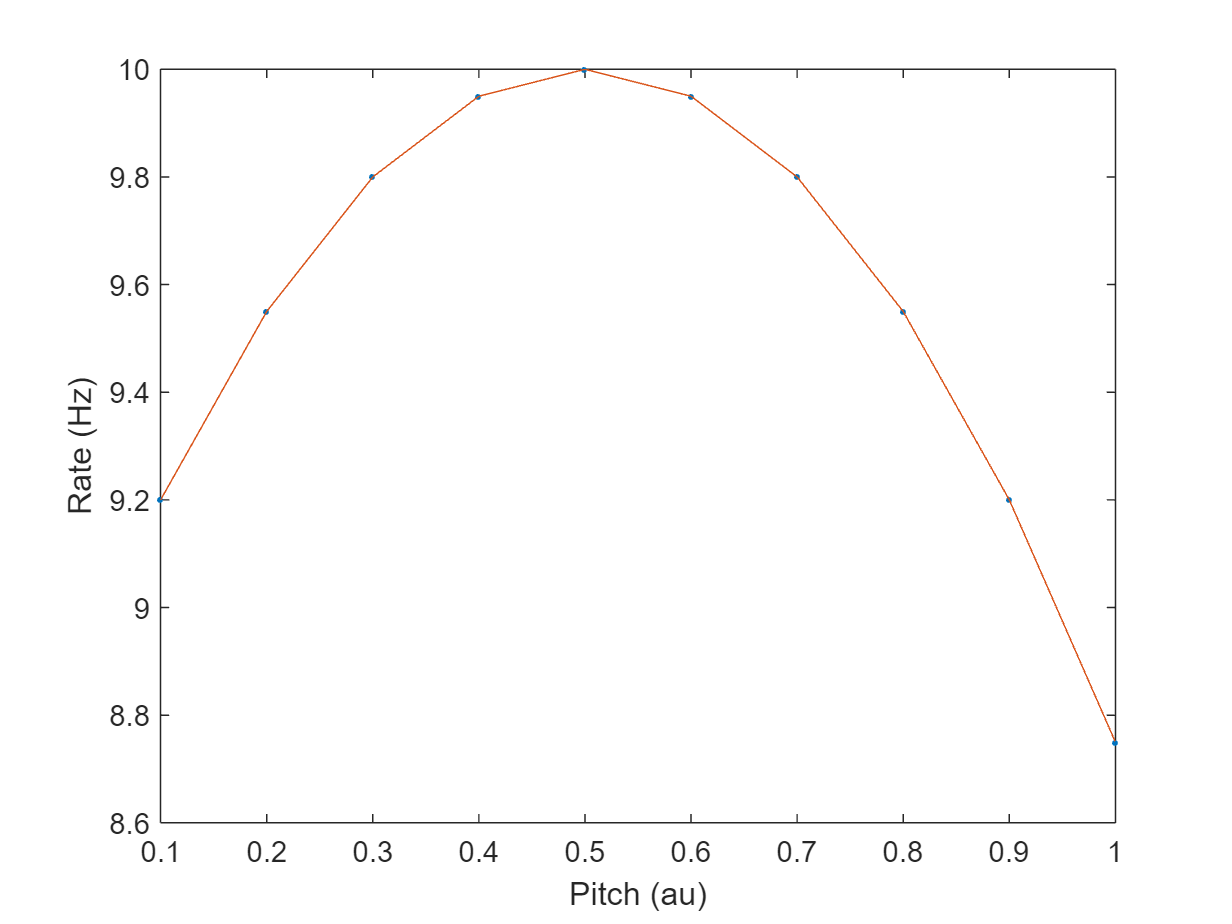

clf;
% First plot the data
plot(pitch,meanFiringRate,'.');
% Then plot the fitted curve 
hold on
plot(pitch,quadratic(bestParms,pitch))
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

Not surprisingly (because there was no noise and we knew the underlyig relationship was a quadratic) , the algorithm found the correct solution. Let's make this a little harder by including some noise:

rng default
noiseLevel = 0.1;
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel,'model','tuned');
guess = [1 1 1];
bestParms = lsqcurvefit(quadratic,guess,pitch,meanFiringRate);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


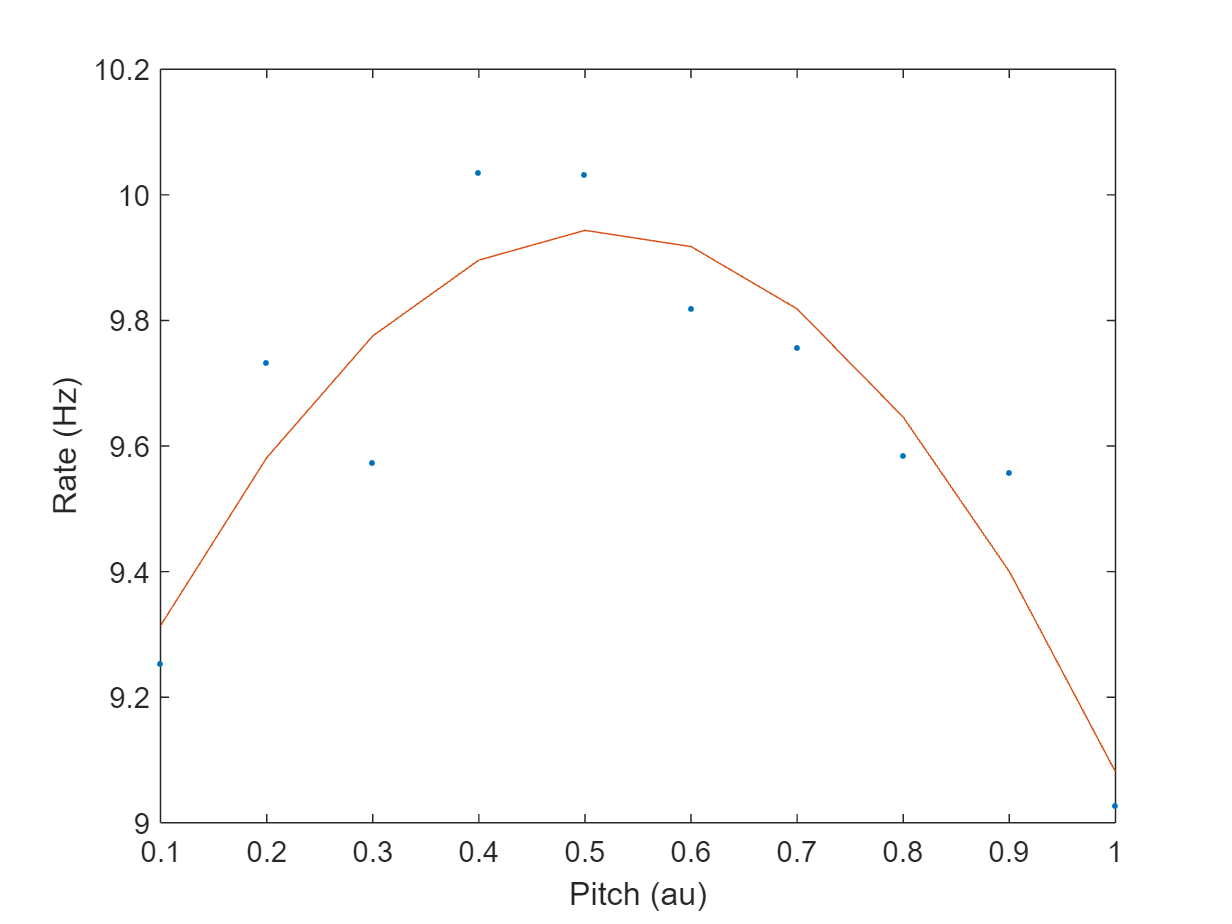

clf;
plot(pitch,meanFiringRate,'.');
hold on
plot(pitch,quadratic(bestParms,pitch))
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

As you can see, even with the noise in the measurements, the algorithm finds a pretty good fit that describes the non-monotonic relationship between `pitch` and `meanFiringRate`. This fit is the "best" fit in the sense that the total squared distance between the fitted model and the actual data points is the smallest possible. We can visualize this as:

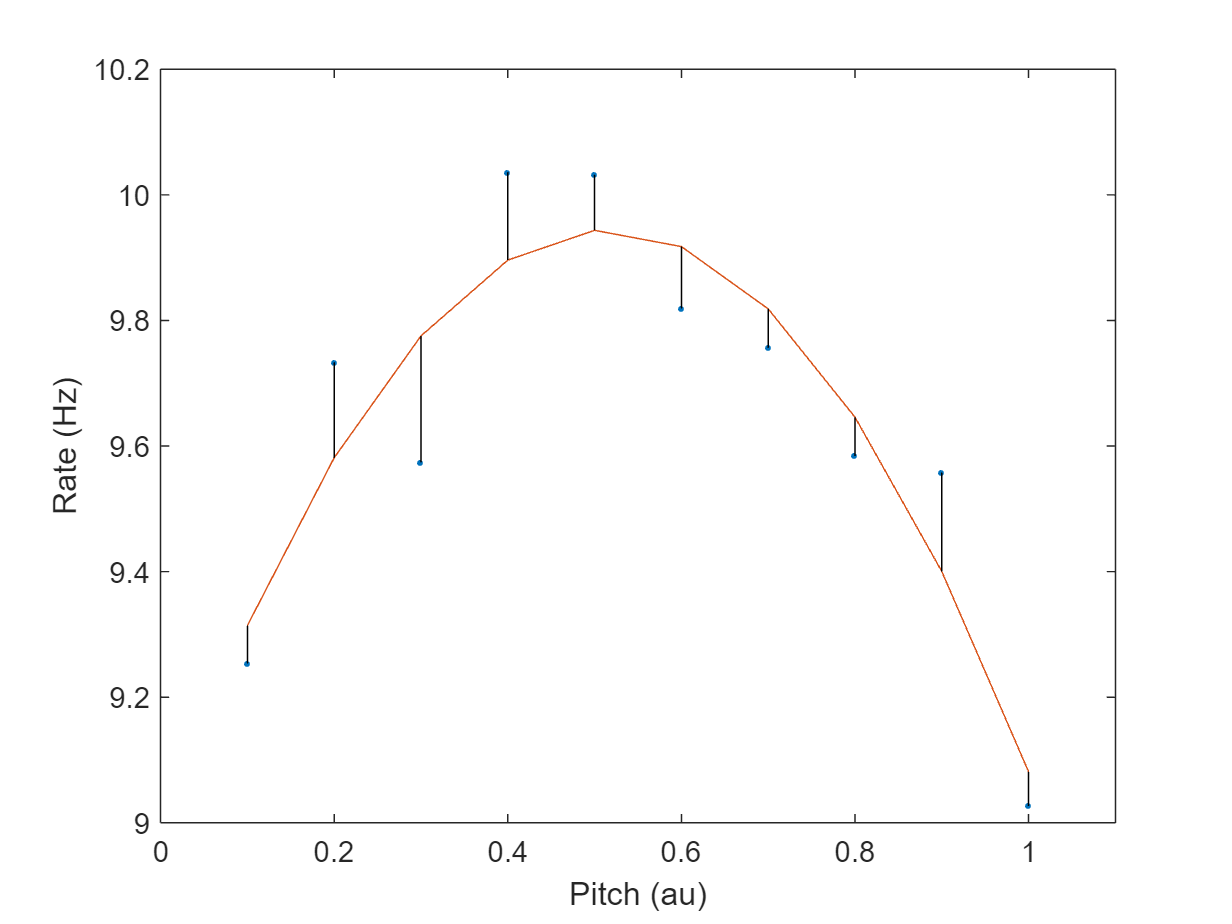

clf;
plot(pitch,meanFiringRate,'.');
hold on
plot(pitch,quadratic(bestParms,pitch))
%Show residuals
line([pitch  pitch]',[quadratic(bestParms,pitch) meanFiringRate]','Color','k')
xlim ([0 1.1])
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

The "lsq" ("least squares") in  `lsqcurvefit` refer to the sum of the squares of the differences between the model and the data: that is what the algorithm minimized. They are also called residuals and we can simply calculate them:

residuals = quadratic(bestParms,pitch)-meanFiringRate;
% Or, we can ask |lsqcurvefit| to return the residuals |R|:
%[~,~,R] = lsqcurvefit(quadratic,guess,pitch,meanFiringRate);

It should be intuitive that the residuals provide a measure of how good the fit is. Formally, we compare the residual sum of squares (i.e. how much the fit *failed* to capture) with the total sum os squares (how much a perfect fit would capture). This results in a measure called $R^2  = 1 -\frac{SS_{residuals}}{SS_{total}}$. 

globalMean = mean(meanFiringRate);
totalSumSquares = sum((meanFiringRate-globalMean).^2)

totalSumSquares = 0.9042

residualSumSquares = sum(residuals.^2)

residualSumSquares = 0.1398

rSquared = 1-residualSumSquares./totalSumSquares

rSquared = 0.8454

You can interpret this number as the fraction of the variance that the fit explains. The variance in this case is the variation of the data around the global mean (i.e. how much firing rate goes up and down as a function of pitch). Just like the Pearson and Spearman correlation, this number gets smaller when the relationship is not as clean (not as well captured by the model). For instance:

noiseLevel = 0.75;
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel,'model','tuned');
guess = [1 1 1];
[bestParms,~,residuals] = lsqcurvefit(quadratic,guess,pitch,meanFiringRate);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


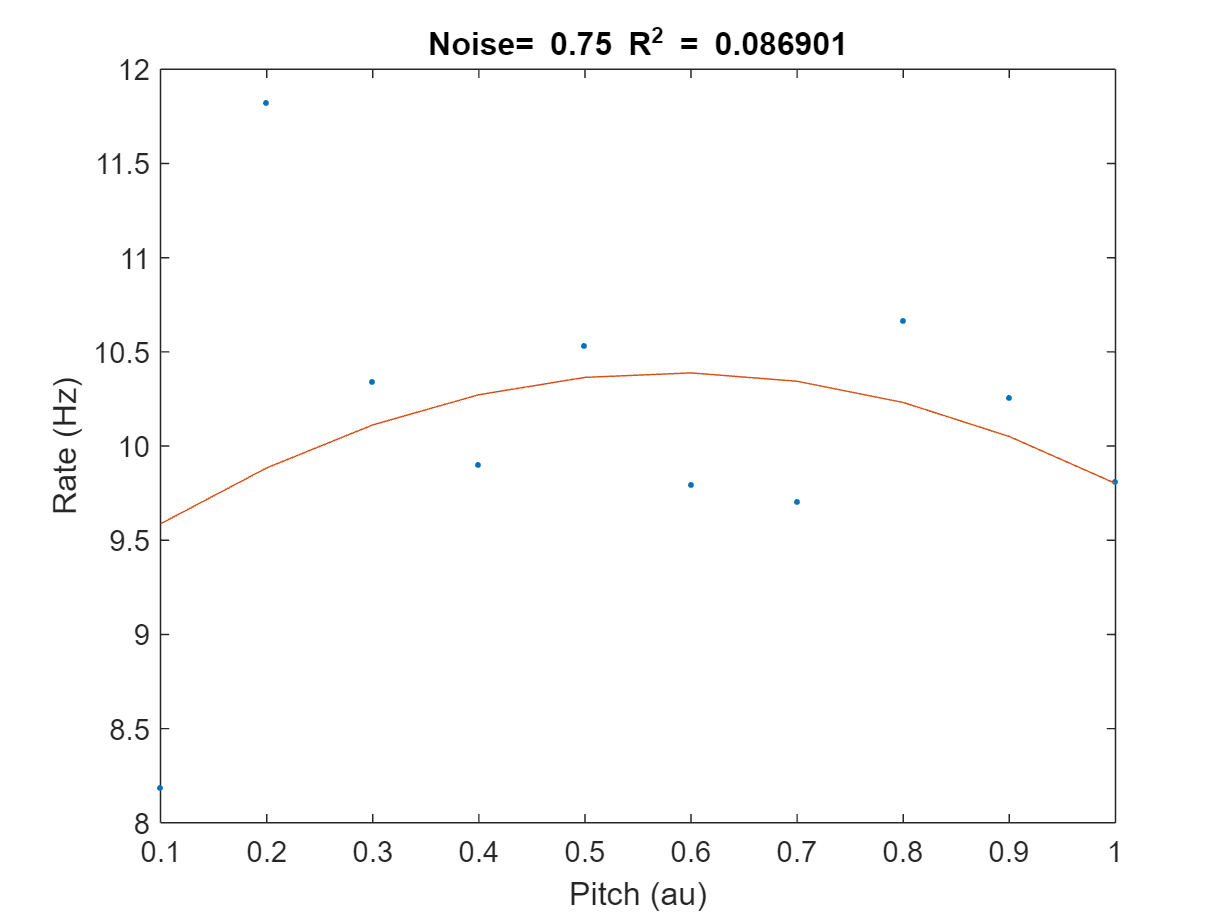

clf;
plot(pitch,meanFiringRate,'.');
hold on
plot(pitch,quadratic(bestParms,pitch))
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'

globalMean = mean(meanFiringRate);
totalSumSquares = sum((meanFiringRate-globalMean).^2);
residualSumSquares = sum(residuals.^2);
rSquared = 1-residualSumSquares./totalSumSquares;
title (['Noise= ' num2str(noiseLevel) ' R^2 = ' num2str(rSquared)]);

Note that, even though this quantity is referred to as $R^2$, it can actually have a negative value. From the definition above you can see that happens when the residual sum of squares is larger than the total sum of squares. What this means is that the model is worse than a model that assumes that the pitch has no influence on the mean firing rate (becuase that model would predict `globalMean` for every `pitch` and hence have a residual sum of squares equal to the total sum of squares. This "model" has R^2 ==0, hence any model with a negative $$R^2$ is worse than this "no relationship" model.

`lsqcurvefit` allows you to answer the question: "how much do my data look like any arbitrary function". Because you have complete control of the function this allows you to test very complex hypotheses about your data. Alternatively, it allows you to reduce the complexity of the data descritpion. For instance in the example above, we go from a description that requires 10 numbers (the firing rate at each pitch) to one that requires only 3 numbers. That is progress because it uncovers a regularity in the data. 

The assumptions underlying `lsqcurvefit` are that the measurements have normally distributed noise, and you can only use `lsqcurvefit` if you have a specific hypothesis for an underlying model that you can parametrize (i.e. write as a function with parameters). 

### Alternative curve fitting approaches

`nlinfit` in the Statistics and Machine Learning Toolbox:

- Works only for vector valued dependent variables.  In other words in the curve you are fitting ($y=f(x)$ , $y$ has to be a vector, not a matrix). If your $y
$ is a matrix, you can always rewrite the fitting funciton to return a vector, so this is not a major problem.

- Has options for robust fitting. One of the common problems in curve fitting is that outliers can drive the results. The reason for this is that residuals add as squares , hence the algorithm that minimizes the squares ("least squares") will try really hard to incorporate such an outlier. `nlinfit` uses a weighting function to increase robustness (RobustWgtFun) : it specifies how much weight each data point gets in the algorithm. For instance, you can chose to weigh data points exponentially based on the residuals ($w = exp(-r^2)$). 

- Provides more detailed info about the statistics of the resulting fit.

`lsqcurvefit` in the Optimizaiton Toolbox 

- works for vector valued dependent variables as well as matrix valued dependent variables

- Has no options for robust fitting (so you should check your results to see if they are driven by outliers; sometimes it is enough to show that essentially the same fit reslts if you leave out that one outlier).

- Has options to put bounds on the fitted parameters 

`fit` in the Curve fitting toolbox

- Has the most options: you can Exclude certain data points, you can add smoothing to the data, 

- Has options to put bounds on the fitted parameters. 

- Has options for robust fitting

- Provides a detailed fit model as output that can be used in subsequent analyses. 

- Has options to weigh specific data points differently (for instance if the y values are based on some average over trials, you could weigh these by the inverse of the standard deviation; that way you tell the algorithm to rely more on the reliable estimate (small stdev) than the more unreliable estimates. This can improve the robustness of a fit.

- Takes tables as input, which can make your code more readable.

In the past, I have mainly used lsqcurvefit, but with recent improvements and additions, it looks like `fit` may be winning the features battle. So let's redo the analysis above, now with the `fit` function.

% Regenerate the data
rng default; 
noiseLevel = 0.1;
meanFiringRate = neuralResponse(pitch,'spontaneous',spontaneousRate,'noise',noiseLevel,'model','tuned');
guess = [1 1 1];

First we have to specify what kind of function we want to fit. This is done with the `fittype` function, this works for any arbitrary function, but it also has a built-in library of common functions, including a quadratic function ('`poly2'`):

ft = fittype('poly2');
[modelFit,gof] = fit(pitch, meanFiringRate,ft)

modelFit =      Linear model Poly2:
     modelFit(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      -3.665  (-5.119, -2.21)
       p2 =       3.772  (2.131, 5.414)
       p3 =       8.974  (8.581, 9.367)

gof = struct with fields:
           sse: 0.1398
       rsquare: 0.8454
           dfe: 7
    adjrsquare: 0.8012
          rmse: 0.1413


Note that `modelFit` is an object that contains much there is to know about the fit, while the `gof` struct has some additional 'Goodness of Fit' information The `modelFit` object provides a lot of useful functionality for post-processing (see `help cfit`). 

We can use it to plot the results and inspect the residuals. 

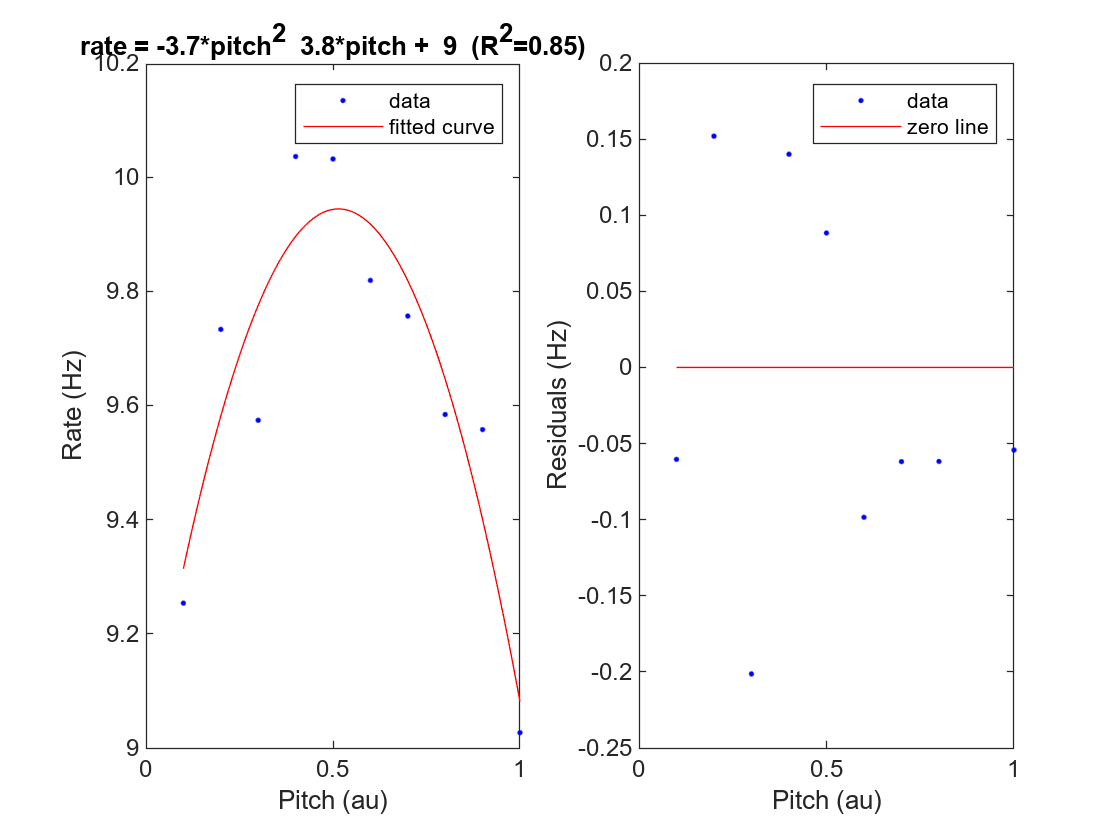

clf;
subplot(1,2,1);
plot(modelFit,pitch,meanFiringRate ) % Compare data and model
xlabel 'Pitch (au)'
ylabel 'Rate (Hz)'
% Extract model estimates:
txt =sprintf('rate = %3.2g*pitch^2  %3.2g*pitch +%3.2g  (R^2=%3.2g)',modelFit.p1,modelFit.p2,modelFit.p3,gof.rsquare);
title(txt)
subplot(1,2,2)
plot(modelFit,pitch,meanFiringRate,'Residuals'); %Show residuals
xlabel 'Pitch (au)'
ylabel 'Residuals (Hz)'

Let's make sure that lsqcurvefit and fit really did come up with the same solution: 


[parms,~,R] = lsqcurvefit(quadratic,guess,pitch,meanFiringRate);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


globalMean = mean(meanFiringRate);
totalSumSquares = sum((meanFiringRate-globalMean).^2);
residualSumSquares = sum(R.^2);
rSquared = 1-residualSumSquares./totalSumSquares

rSquared = 0.8454

gof.rsquare

ans = 0.8454

parms

parms =    -3.6646    3.7723    8.9736


[modelFit.p1 modelFit.p2 modelFit.p3]

ans =    -3.6646    3.7723    8.9736


All is good; R-squared and the parameter estimates are the same in the two approaches.

### Local Minima

Above you can see several instances where Matlab complained about "Local Minimum Found". This is an important warning and caveat about nonlinear curve fitting. To understand this, we first need to understand when a fit is nonlinear. What matters in this context is how the parameters you estimate appear in the function. In this function : $y= ax +bx^2+cx^3
$ the values of $y$ depend *linearly* on the parameters $a,b,c$. The fact that $x
$ appears as $x,x^2, x^3$  does not matter; this is a linear model. 

For linear models, there is only *one* best solution, and curve fitting is *guaranteed *to find it. This is called the global optimum (or the global *minimum* because it mimizes the residuals between the model and the data).

Functions $y = sin(a*x+b) $ , or $y= log(a*x+b)$depend nonlinearly on the parameters $a$ and $b$. The curve fitting routines in Matlab will try to find the best solution, but there is *no guarantee *that they can find it. In the space of all solutions, the algorithm starts somewhere (at an initial guess of values for the parameters $a,b,c$) and then finds the best solution from that starting point. You should think of this search as a walk to the valley in the mountains; the algorithm will go downhill to find the nearest valley, but it has no way of knowing whether there may be a deeper valley on the other side of the next mountain. That is what Matlab tells you when it warns about the 'local minimum found'; this is the best solution given the starting point.

Because of this, you should always specify a reasonable initial guess ('StartPoint' in the fit function); that will improve the odds of finding the best solution. However, if you have no information to help you pick a good initial guess, but you do have a range of parameter values that seem reasonable, then you can simply run the same fit many times, starting from a different initial StartPoint. Do this in a loop, and each time compare the goodness of fit (gof.rsquare above) to the previous result. If the R-squared is better, store the new model, and keep going until you've sampled a good fraction of all possible starting points. This is a brute force search (essentially dropping the algorithm in different places in the mountains, asking it to walk to the nearest valley each time, and keep track of the height of the valley so that you can pick the lowest value at the end). This procedure is not guaranteed to find the best solution either, but as long as your model is not too complex, it usually works. 

Given the major advantage of linear models it is often worth considering whether your model cannot be reformulated to make it linear. A common example is the model $y = a*exp(b*x)$, this model is nonlinear in b, so you may be tempted to use a nonlinear fitting routine. However, you can easily transform the dependent variables $y$ to $z = log(y) = log(a*exp(b*x)) = log(a) + b*x = c+ b*x$. So, by fitting a linear model (with parameters $b
$ and $c$ ) to the quantity $log(y)
$ you can estimate the original nonlinear model with the guarantee of a unique, global optimum. Whenever you can transform your model to a linear model, you should.

Note that the `fit` function will not accept a `StartPoint` input if the underlying model is linear. fit determines this on the basis of the `fitType` object. In the example above , we used the `poly2` fitType, `fit` knows that that is a linear function, and therefore uses an algorithm that works for linear curve fitting (and that does not need or even allow a StartPoint). That is why the call to fit did not use the `guess `variable. 

## The General Linear Model

The GLM is a technique to extract regularities from data when you either do not have a specific model in mind, or if you have multiple models in mind. It allows you to answer questions like: do my data look more like this model or like that model? 

The GLM is used in many fMRI BOLD signal analyses. For instance we can rertun to the faces/houses experiments from the Spectral Analysis module:

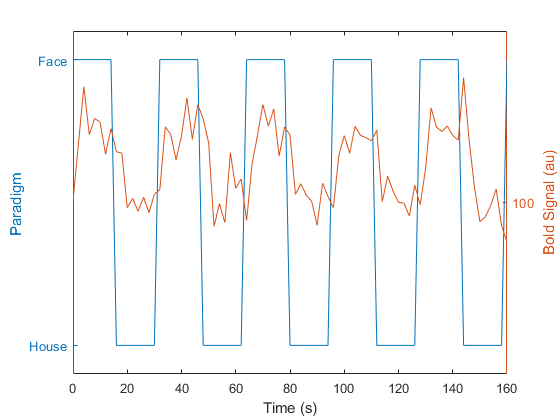

load ../data/boldData
clf;
yyaxis left
plot(boldTime,paradigm);
ylabel('Paradigm ');
set(gca,'YLim',[-0.1 1.1],'YTick',[0 1],'YTickLabel',{'House','Face'})
yyaxis right 
plot(boldTime,bold);
xlabel 'Time (s)'
ylabel('Bold Signal (au)');
set(gca,'YLim',[99 101],'YTick',100)

Previously we analyzed this using the Fourier transform to extract periodic response of the voxel. Here' we'll use a more standard approach based on the GLM. 

The essential element in the GLM is the predictor function (Also called regressor). Essentially we ask the question: does the signal look like a specific predictor? For instance one might ask whether the time course of the voxel looks like the paradigm time course. In other words is the signal "high" during Face blocks and "low" during House blocks? 

We combine this predictor (our hypothesis) with a special constant predictor to create what is called the design matrix:

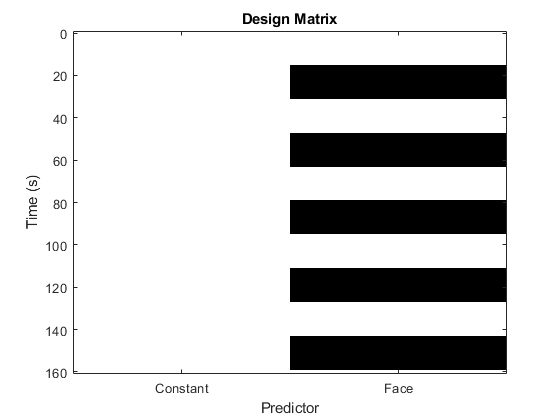

designMatrix = [ones(size(boldTime)), paradigm];
clf;
imagesc(1:2,boldTime,designMatrix)
xlabel 'Predictor'
ylabel 'Time (s)'
set(gca,'XTick',[1 2],'XTickLabel',{'Constant','Face'});
colormap gray
title 'Design Matrix'

Each column of the design matrix asks one question. The first asks: "is there some aspect of the data that does not change over time? How large is it?". The second column asks: "to what extent does the signal look like the alternation of two phases (high during Face blocks, low during House blocks). In Matlab you can get an answer to these questions using the `regress` function:

[beta,betaInt,residuals,residualsInt,stats] =regress(bold,designMatrix); %#ok<ASGLU> 

The first output argument of the `regress` function is called the beta weights. There is one weight per predictor and it states how much the signal looks like that particular predictor. In this case the values are:

beta

beta =   100.0958
    0.2463


Which means that the mean of the signal was ~100 (beta(1)) and that the Face predictor had a weight of ~0.25. This means that the best model (given these two predictors) to describe these data is 

modelPrediction = beta(1) + beta(2)*paradigm;  


This is the reason that this is called a *linear* model: the signal is modeled as the linear combination of 1 or more functions (predictors). The weight that each predictor gets in this combination is the beta  weight.

As an aside, please note that because Matlab can do linear algebra, a better way to write this is  `modelPrediction = designMatrix*beta;` This notation also shows that an alternative way to do linear regression in Matlab is to invert the equation:  `beta = designMatrix\bold;` This is called a left divide (\) and essentially we are just dividing the `bold` signal by the `designMatrix` to get the `beta` values. This will result in the same values as the output of `regress`, but it does not do any of the statistical analyses.

Now let's compare this GLM prediction with the orignal signal:

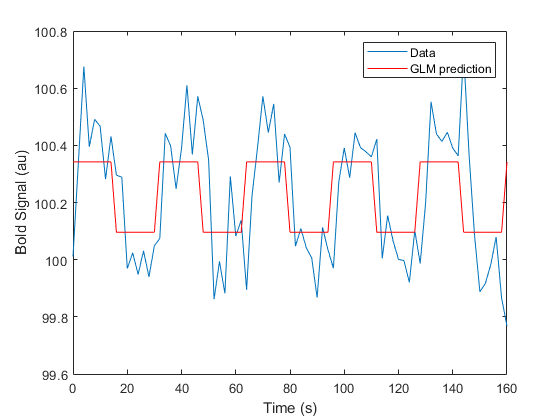

clf;
plot(boldTime, bold);
hold on;
plot(boldTime,modelPrediction,'r');
legend ('Data','GLM prediction')
xlabel 'Time (s)'
ylabel('Bold Signal (au)');

The GLM has captured the main Face related modulation in the signal (as well as the mean signal). The second output argument helps you determine whether a predictor contributes significantly to the signal becuase `betaInt` provides the confidence intervals of the `beta` values. If these confidence intervals overlap with zero then you cannot reject the null hypothesis that the predictor has no significant contribution. In this case:

betaInt

betaInt =   100.0344  100.1571
    0.1601    0.3326


Which shows that according to the GLM, the constant predictor (i./e. the mean signal) has a value 100.03 and 100.16 with 95% certainty. The paradigm predictor is between 0.16 and 0.33 with 95% certainty, so we can conclude at the p<0.05 level that the Face predictor significantly modlated the bold signal. If a significance level of 0.05 is too lenient, you can specfy a different significance level in the call to `regress`.

The `regress` function returns the best linear model (given the predictors in the design matrix). "Best" model in this case means the same as for `lsqcurvefit` : this model minimizes the sum of the squared differences between the model and the data. Just as with `lsqcurvefit` we can determine how good the model is by calculating $R^2$. This is simplified by the fact that `regress` returns the residuals:

totalSS =  sum((bold-mean(bold)).^2);
rSquared = 1- sum(residuals.^2)./totalSS

rSquared = 0.2902

In fact this value is also in the `stats` ooutput argument which furthermore contains an F-statistic and corresponding p-value for the GLM as a whole. This means that if the F is large (and p below your significance threshold) then the model you specified in the `designMatrix` explains a significant amount of the variance in the data. In general this p-value does not tell you which predictor (i.e. column in the design matrix) contributes significantly, just that the model as a whole provides some statistically meaningful insight into the data. (To assess significance of individual predictors, you use the `betaInterval` values). 

In the model (`designMatrix`) above, we assumed that the BOLD signal in the voxel would go up at the same time as the Face was shown on the screen. Of course, we know that BOLD signals are delayed due to the hemodynamic response. A simple way to model this is to simply delay the paradigm vector by ~6 seconds  (a more accurate way would be to convolve (i.e. filter) the paradigm vector with a function representing the HRF; this reflects the fact that the HRF is not just a delay, but it also changes the shape of the expected BOLD signals, we'll ignore that here). 

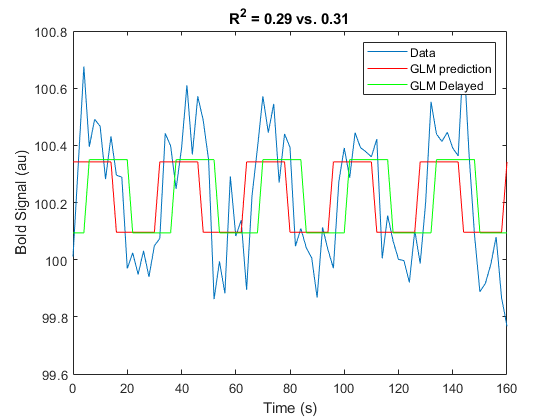

delay = 3; % Model that the paradigm induces BOLD changes with 3 TRs delay
delayedParadigm  = [zeros(delay,1);paradigm(1:end-delay)];
designMatrix = [ones(size(boldTime)), delayedParadigm];
[beta,betaInt,residuals,residualsInt,stats] =regress(bold,designMatrix); %#ok<ASGLU> 
delayedModelPrediction = designMatrix*beta;
clf;
plot(boldTime, bold);
hold on;

plot(boldTime,modelPrediction,'r');
plot(boldTime,delayedModelPrediction,'g');
legend ('Data','GLM prediction','GLM Delayed')
xlabel 'Time (s)'
ylabel('Bold Signal (au)');
rSquaredDelayed = 1- sum(residuals.^2)./totalSS;
title(sprintf('R^2 = %3.2g vs. %3.2g',rSquared,rSquaredDelayed))

The GLM Delayed model is , as expected, a better fit with the BOLD signal; the R-squared statistic captures this nicely. Modifying predictors by delaying them (or reshaping them with a filter like the HRF) is a common way to improve model fits in the GLM framework and this flexibility is part of its appeal.

Another strength of the GLM is that you can add predictors very easily and determine whether they help to describe the data. For instance, if we did motion correction on the scans (to account for any small subject movements during the scan), then we usualy obtain a signal that specifies the motion of the subject. To investigate whether this affected the BOLD signal (or rather to remove it), we can include the motion signals in the regression.

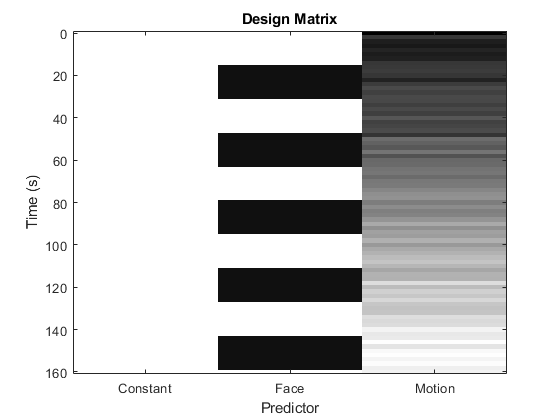

% Create a fake motion signal of a subject slowly drifting out of the scanner 
motion  = 0+ boldTime/max(boldTime)+0.05*randn(size(boldTime)); 

% add it to the design matrix:
designMatrix = [ones(size(boldTime)), paradigm, motion];
clf;
imagesc(1:3,boldTime,designMatrix)
xlabel 'Predictor'
ylabel 'Time (s)'
set(gca,'XTick',1:3,'XTickLabel',{'Constant','Face','Motion'});
colormap gray
title 'Design Matrix'

And then perform the regression with the design matrix with three predictors. 

[beta,betaInt,residuals,residualsInt,stats] =regress(bold,designMatrix);

Looking at `stats` output we see tha the full GLM model is still significant but looking at the beta values, we see that the confidence interval for beta(3), the beta weight that deteremines the contribution of the motion predictor straddles zero:

betaInt

betaInt =   100.0376  100.2426
    0.1524    0.3266
   -0.2312    0.0691


This implies that the bold signal was not significantly modulated by the motion signal (not surprising in these fake data). 

With regressors like these motion signals we are often not interested in the significance. We know they're likely a factor in the data, and we'd like to "get rid of them". That is what including them as 'nuisance regressors' does. The GLM tries to explan the BOLD signal as a (linear) combination of the columns of the design matrix. Anything that is explained by column 1 is not explained by column 2. In our example, the parts of the signal that are correlated with motion are no longer used to explain the face/house response of the voxel. So, in essence we get a cleaner estimate of the modulation that can only be explained by the face/house alternation.

An important constraint on the choice of predictors is that they should be linearly independent. In the example data for instance, once you've included a Face predictor you cannot also include a House predictor because the House predictor is perfectly (linearly) predictable from the Face predictor. (Face = 1-House). If one predictor is a linear combination of one or more of the other predictors, the `regress` function will issue a warning that the design matrix is 'rank deficient'. Do not ignore this warning, as the results will be uninterpretable. 

### The *Generalized* Linear Model

The General Linear Model (aka  linear regression) assumes that the noise in the measurements is normally distributed and then finds the best fitting model consisting of a linear combination of the predictors. The user has complete control over the choice of predictors and this makes the potential analysis very flexible. 

If your data do not match the normality assumptions of the general linear model then you may have to use what is called the Generalized Linear Model (confusingly, also abbreviated as GLM!). This analysis follows similar lines (i.e. you define a design matrix to specify the components of a model) but it has two additional features. First, you can specify the kind of measurement noise. This is particularly useful for spike data (poisson noise) or for percentage correct performance data (binomial noise). Second, you can specify how you think individual predictors are combined : i.e. not linearly but by some specific linking function. This helps when modeling data where you expect some kind of saturation or exponential increase of the influence of the predictors. In Matlab the `glmfit` function calculates Generalized Linear Models. By specifying normal noise and an identity link function it can also calculate general linear models, so getting to know it may be a good investment for current and future analyses.  

## Summary

There are many ways to answer the question "does this look like that?". If you're comparing only two vectors (e.g time series) of data, and you only want to know whether they look like each other (and not how they look) then correlation measures are appropriate. Use Pearson if you can reasonably make the assumption of a linear relationship, or Spearman if you're only confident that it is a monotonic relationship.

If you want to compare multiple vectors with each other there is the issue that just becuase `a` is correlated with `b` and `b` with `c`, then inevitably there is some correlation between `a` and `c`. Most fMRI functional connectivity analyses ignore this and simply report the Pearson correlation for all pairs. 

Often, however, you really want to know how much `a `look likes `c` while ignoring the similarity that just happens becuase both` a` and `c` look like `b`. A straightforward extension of correlation that computes such measures of similarity is called the partial correlation. The `partialcorr` function in Matlab computes it and, just like `corr`, it has Pearson and Spearman variants. 

Alternatively, however, you can also use a GLM to quantify relationships/similarities among time series . From the GLM perspective you're asking whether `a `can be described as a linear combination of `b` and `c`. In other words, you create a design matrix in whcih one column is `b`, the other is `c` (and a column of ones to represent the constant term) and then use `glmfit` or `regress` to find the beta values. The beta value corresponding to the `c` column  will relfect the (linear) association between `a` and `c` that cannot be explained by `b`. 

These correlation or regression based approaches to "does this look like that?" typically focus on the statistical significance of the correlations. For instance, in a typical fMRI results you'll see a colorful map of statistics on the brain representing the statistical strength of the relationship between the BOLD time series in the voxel and the time course of the experimental paradigm (e.g. Faces/Houses). The actual parameters that are estimated (the betas in the GLM, for instance) are usually not reported . This can be misleading as a parameter can be significant and yet have a very small influence on neural activity (this mainly happens in studies that have hundreds of subjects; very small but real effects become statistically significant due to the large N, but this does not necessarily imply that they are important). This is another example of a bias in the research literature towards model/hypothesis testing (p-values), as opposed to the often more meaningful model estimation (betas, parameters).

With curve-fitting you not only ask "does this look like that?", but can also give a succinct description ( a few parameters) of what "this" looks like. A prototypical example is a tuning curve; you can describe the tuning of a V1 neuron to oriented bars as a list of numbers that give the response for each orientation. But once you have the concept of a tuning-curve, and formalized it as a Gaussian, you can now describe each neuron with just a few numbers; it preferred orientation, its baselie and peak firing rate, and the tuning width. Such a quantification of a neuron is powerful as it automatically includes predictions of the response to orientations that weren't used in the experiment,and this quantification can be used in models of the circuitry. Compare that richness to the poverty of the statement  "the neuron's firing rate was significantly modulated by the orientation of the bars". 